Calculation of population of NV- center under zero-field (B = 0), using equation (11) from [http://arxiv.org/abs/2104.00744](http://arxiv.org/abs/2104.00744)

#### The parameters

Obtained from Robledo, L., Bernien, H., Sar, T. Van Der, & Hanson, R. (2011). Spin dynamics in the optical cycle of single nitrogen-vacancy centres in diamond. *New Journal of Physics*, *13*(2), 25013–25024. https://doi.org/10.1088/1367-2630/13/2/025013

clear 
clc
close all

K0 = zeros(7,7);
 
beta = 0.03;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;

### The rate equations

ode1 = @(t, n) K0(3,1)*n(3) + K0(7,1)*n(7) - K0(1,4)*n(1);
ode2 = @(t, n) K0(5,2)*n(5) + K0(7,2)*n(7) - K0(2,5)*n(2);
ode3 = @(t, n) K0(6,3)*n(6) + K0(7,3)*n(7) - K0(3,6)*n(3);
ode4 = @(t, n) K0(1,4)*n(1) - (K0(4,1) + K0(4,7))*n(4);
ode5 = @(t, n) K0(2,5)*n(2) - (K0(5,2) + K0(5,7))*n(5);
ode6 = @(t, n) K0(3,6)*n(3) - (K0(6,3) + K0(6,7))*n(6);
ode7 = @(t, n) K0(4,7)*n(4) + K0(5,7)*n(5) + K0(6,7)*n(6) - (K0(7,1) + K0(7,2) + K0(7,3))*n(7);
odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

## Solving the system numerically

### Initial conditions

cond1 = 1/3;
cond2 = 1/3;
cond3 = 1/3;
cond4 = 0;
cond5 = 0;
cond6 = 0;
cond7 = 0;
conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

### Using ode45 to solve the equations

code provided by Professor Takahashi

[t, n_res] = ode45(odes, [0:5e-3:20000e-3], conds);

## Plotting

### Plotting only n1, n2, and n3

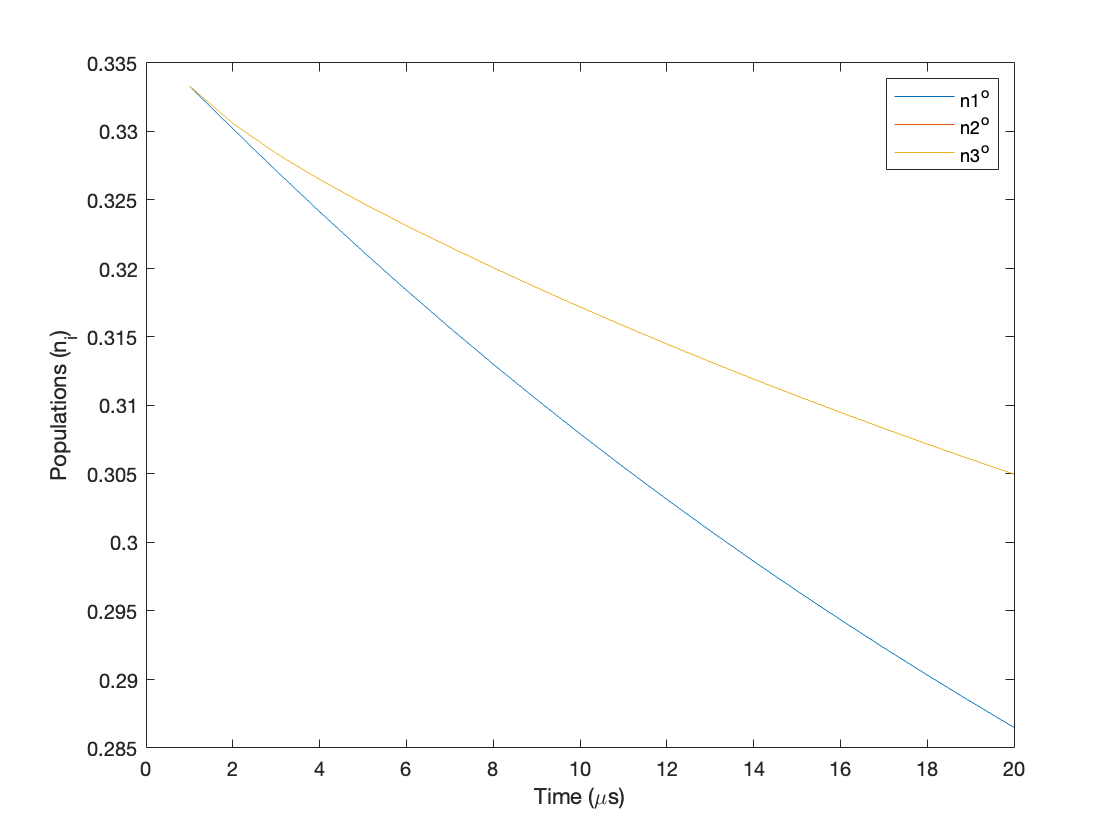

% figure; plot(sol.x,sol.y)
% legend
plot(n_res(:,1));
hold on;
plot(n_res(:,2));
hold on;
plot(n_res(:, 3));
hold off;
xlim([0 20]);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o");

#### Plotting all the populations

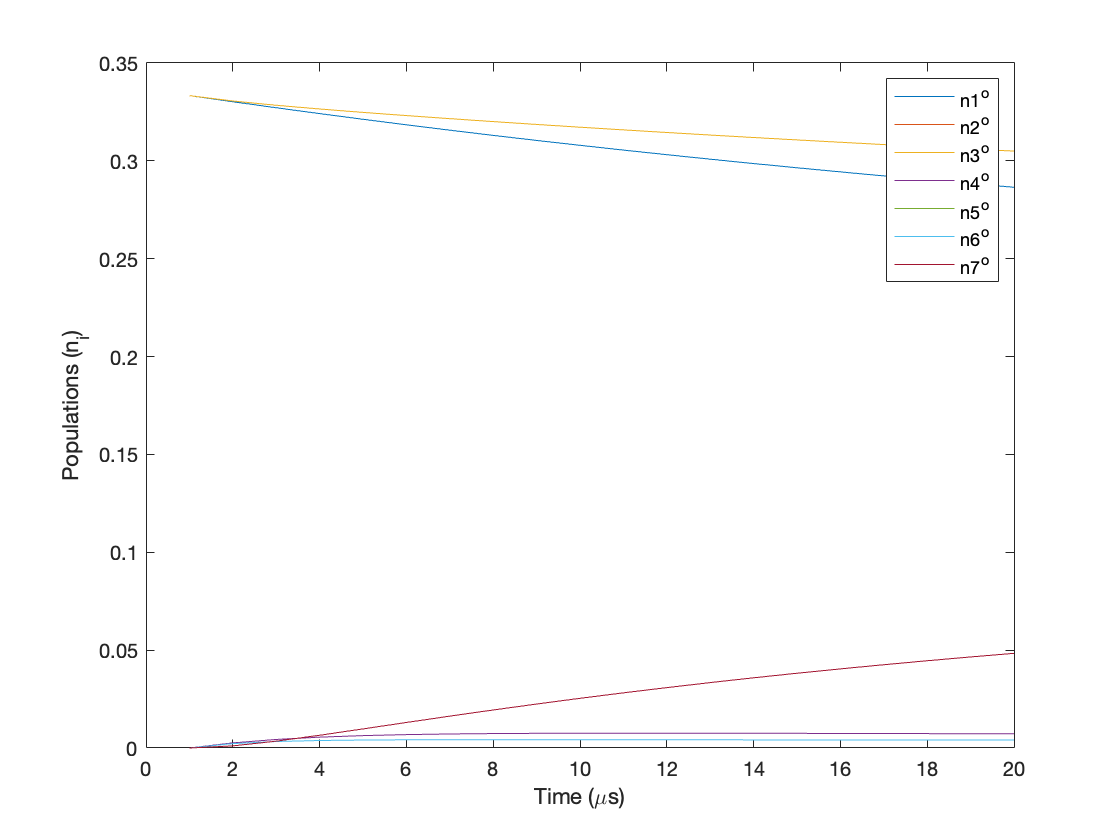

plot(n_res);
xlim([0 20]);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");

## Solving the system analytically (ignore this part)

### Initial conditions

% cond1 = n01(0) == 1/3;
% cond2 = n02(0) == 1/3;
% cond3 = n03(0) == 1/3;
% cond4 = n04(0) == 0;
% cond5 = n05(0) == 0;
% cond6 = n06(0) == 0;
% cond7 = n07(0) == 0;
% conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

% sol = dsolve(odes, conds)
% disp(sol.n01)

% fplot(sol.n01)  % was able to obtain analytical solutions, but plotting takes too long (5+ minutes)

function sum = NV_sum(i, K0, n0)
%     syms sum(t);
    sum = 0;
    for j = 1 : 7
        sum = sum + (K0(j,i) * n0(j) - K0(i,j) * n0(i));
    end
end
